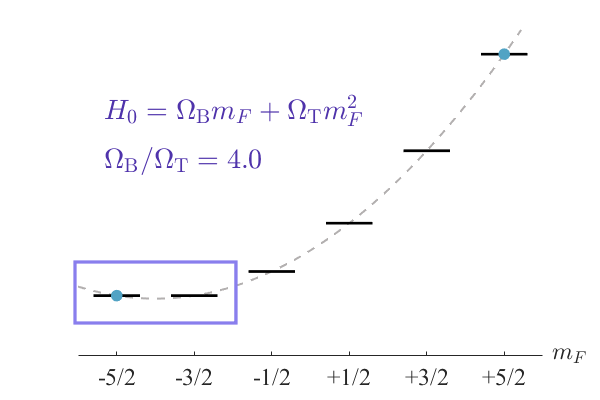

% Fig. 2 %

clear all;
close all;

f1 = figure;
a1 = axes;
set(a1,'YColor','None','FontName','Times New Roman',...
    'FontSize',18);

hold on;
x = [-3:0.1:3];
ratio = 4.0;
y1 = x.^2+ratio*x;
l1 = plot(a1,x,y1,'--','Color',[0.70,0.69,0.69],'LineWidth',1.5);

offset = 0;
for k = -5/2:1:5/2
    l = plot(a1,[k-0.3 k+0.3],[k.^2+ratio*k+offset k.^2+ratio*k+offset],...
        'Color','k','LineWidth',2);
    %if k == -5/2 || k == -3/2
    %    l.Color = [0.31,0.20,0.67];
    %end
end

plot([-5/2 5/2],[(-5/2)^2+ratio*(-5/2) (+5/2)^2+ratio*(+5/2)],...
    '.','MarkerSize',30,'LineWidth',2,'Color',[0.32,0.64,0.77]);

%plot([-5/2+0.3 -3/2-0.3],[(-5/2)^2+ratio*(-5/2)+offset (-5/2)^2+ratio*(-5/2)+offset],...
%    ':','Color',[0.70,0.69,0.69],'LineWidth',1.5);

hold off;

xlim([-3 3]);
ylim([(-5/2)^2+ratio*(-5/2)-5  (+5/2)^2+ratio*(+5/2)+2]);

xticks([-5/2:1:5/2]);
xticklabels({'-5/2' '-3/2' '-1/2' '+1/2' '+3/2' '+5/2'});
xlabel('$m_F$','LineWidth',1,'Interpreter','latex',...
    'FontName','Times New Roman','FontWeight','normal',...
    'FontSize',18,'Position',[3.3548 -7.34667 -1]);
%yticks([]);
%ylabel('E','LineWidth',1,'Interpreter','latex',...
%    'FontName','Times New Roman','FontWeight','normal',...
%    'FontSize',18,'Position',[3.3548 -7.34667 -1]);

annotation(f1,'textbox',...
    [0.1625 0.68108 0.3925 0.09018],...
    'String','$H_0=\Omega_{\rm B}m_F+\Omega_{\rm T}m_F^2$',...
    'Color',[0.31,0.20,0.67],...
    'LineWidth',1,...
    'Interpreter','latex',...
    'FontWeight','bold',...
    'FontSize',21,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'FaceAlpha',0,...
    'EdgeColor','none');
annotation(f1,'textbox',...
    [0.1617 0.56893 0.24997 0.08214],...
    'String','$\Omega_{\rm B}/\Omega_{\rm T}=4.0$',...
    'Color',[0.31,0.20,0.67],...
    'LineWidth',1,...
    'Interpreter','latex',...
    'FontWeight','bold',...
    'FontSize',21,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'FaceAlpha',0,...
    'EdgeColor','none');

annotation(f1,'rectangle',[0.125 0.1925 0.2683 0.1525],...
    'Color',[0.5372 0.4941 0.9294],...
    'LineWidth',2.5);

set(f1,'Visible','on');
set(f1,'Position',[200 200 600 400],'Visible','on');


savefig(f1,'E:\Comagnetometer_Pub\Energy_vs_BT\Degeneracy.fig');
savefig(f1,'E:\Comagnetometer_Pub\Fig2\Degeneracy.fig');
saveas(f1,'E:\Comagnetometer_Pub\Energy_vs_BT\Degeneracy.png');
saveas(f1,'E:\Comagnetometer_Pub\Energy_vs_BT\Degeneracy.eps','psc');
saveas(f1,'E:\Comagnetometer_Pub\Energy_vs_BT\Degeneracy.svg')


save('E:\Comagnetometer_Pub\Energy_vs_BT\Degeneracy.mat');